% Generate a signal with two overlapping chirps
fs = 1000;
t = 0:1/fs:2;
f1 = 100 + 50*t;       % Linear chirp 1
f2 = 250 - 50*t;       % Linear chirp 2 (crosses f1 at t = 1.5s)
x = cos(2*pi*cumtrapz(t, f1)) + cos(2*pi*cumtrapz(t, f2));

% 1. Compute the Wavelet Synchrosqueezed Transform
[sst, f] = wsst(x, fs);

% 2. Extract 2 ridges with a penalty of 20 to handle the crossing smoothly
num_ridges = 2;
penalty_value = 20; 
[fridge, iridge] = wsstridge(sst, penalty_value, f, 'NumRidges', num_ridges);

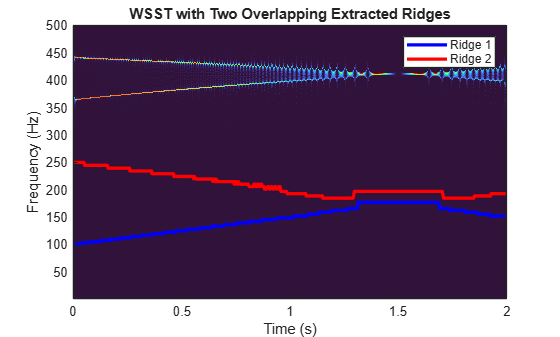

% 3. Plot the WSST scalogram and overlay both extracted ridges
figure;
imagesc(t, f, abs(sst));
axis xy; colormap(turbo); hold on;

% Plot each ridge dynamically
colors = ['b', 'r'];
for k = 1:num_ridges
    plot(t, fridge(:, k), colors(k), 'LineWidth', 2.5);
end

title('WSST with Two Overlapping Extracted Ridges');
xlabel('Time (s)'); ylabel('Frequency (Hz)');
legend('Ridge 1', 'Ridge 2');
hold off;